# Window Functions

Comparison of db magnitude spectra for various window functions.

N = 21;
Rectangular_window = true;
Bartlett_window = true;
Hamming_window = true;
von_Hann_window = true;
Blackman_window = true;

Compute sample amplitudes of window sequences for $n=0,\ldots,N-1$

w1 = ones(N,1);  % Rectangular window
w2 = bartlett(N);
w3 = hamming(N);
w4 = hanning(N);
w5 = blackman(N);

Graph window sequences

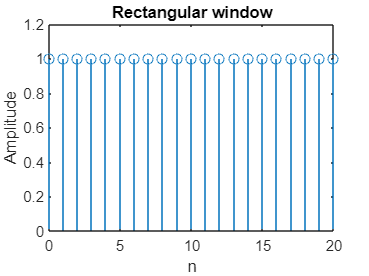

n = 0:N-1;
if (Rectangular_window)
  stem(n,w1);
  axis([0,N-1,0,1.2]);
  title('Rectangular window');
  xlabel('n');
  ylabel('Amplitude')
end

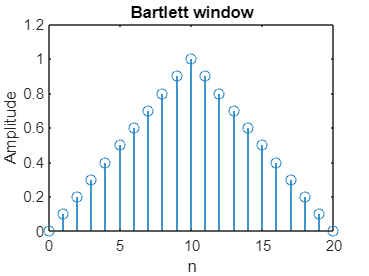

if (Bartlett_window)
  stem(n,w2);
  axis([0,N-1,0,1.2]);
  title('Bartlett window');
  xlabel('n');
  ylabel('Amplitude')
end

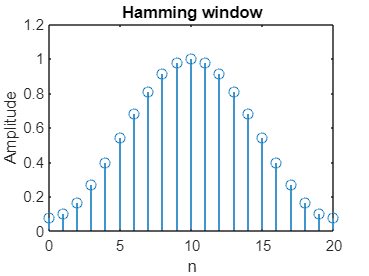

if (Hamming_window)
  stem(n,w3);
  axis([0,N-1,0,1.2]);
  title('Hamming window');
  xlabel('n');
  ylabel('Amplitude')
end

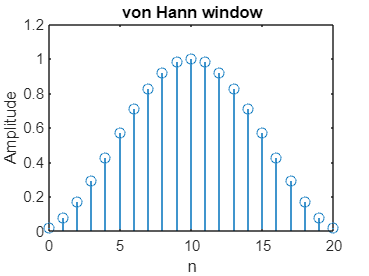

if (von_Hann_window)
  stem(n,w4);
  axis([0,N-1,0,1.2]);
  title('von Hann window');
  xlabel('n');
  ylabel('Amplitude')
end

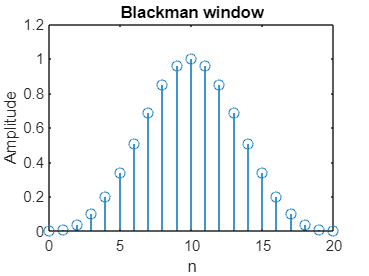

if (Blackman_window)
  stem(n,w5);
  axis([0,N-1,0,1.2]);
  title('Blackman window');
  xlabel('n');
  ylabel('Amplitude')
end

Omg = [0:511]/512*pi;
W1 = dBMag(w1,Omg);
W2 = dBMag(w2,Omg);
W3 = dBMag(w3,Omg);
W4 = dBMag(w4,Omg);
W5 = dBMag(w5,Omg);

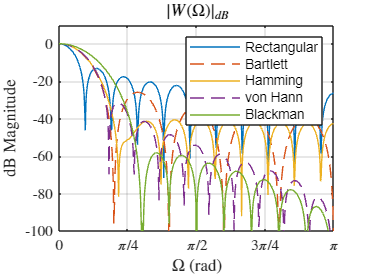

p1 = plot(Omg,W1,'-',Omg,W2,'--',Omg,W3,'-',Omg,W4,'--',Omg,W5,'-'); grid;
axis([0,pi,-100,10]);
set(p1(2),'Visible',Rectangular_window);
set(p1(2),'Visible',Bartlett_window);
set(p1(2),'Visible',Hamming_window);
set(p1(2),'Visible',von_Hann_window);
set(p1(2),'Visible',Blackman_window);
hx = xlabel('$\Omega$ (rad)','Interpreter','latex'); 
hy = ylabel('dB Magnitude','Interpreter','latex');
ht = title('$\left|W\left(\Omega\right)\right|_{dB}$','Interpreter','latex');
hl = legend('Rectangular','Bartlett','Hamming','von Hann','Blackman');
set(gca,'XTick',[0,0.25*pi,0.5*pi,0.75*pi,pi]);
set(gca,'XTickLabel',{'$0$';'$\pi/4$';'$\pi/2$';'$3\pi/4$';'$\pi$'},...
    'TickLabelInterpreter','latex');

Local function to compute dB magnitudes

function WdB = dBMag(w,Omega)
  WdB = 20*log10(abs(freqz(w,1,Omega)/sum(w)));
end